# Chapter 1 Exercises - MATLAB solutions

#### Exercise 1.1

Solve the following IVP using the Euler method with a step length of $h=0.5$. Write down your solutions correct to 4 decimal places.


$$y' + y = 1 - e^{-t}  \qquad t\in [0,4],\qquad y(0)=1.$$


**Solution**

Rearranging the ODE slightly gives $y' = 1 - y -e^{-t}$. Applying the Euler method with step length $h=0.5$:


$$  \begin{array}{rl}
  y_0 &= 1, \\
    t_0 &= 0, \\
    y_1 &= y_0 + h(1 - y_0 - e^{-t_0}) = 1 + 0.5(1 - 1 - e^{0}) = 1, \\
    y_1 &= t_0 + h = 0 + 0.5 = 0.5, \\
    y_2 &= y_1 + h(1 - y_1 - e^{-t_1}) = 1 + 0.5(1 - 1 - e^{-0.5}) = 0.6967, \\
    t_2 &= t_1 + h = 0.5 + 0.5 = 1.0, \\
    y_3 &= y_2 + h(1 - y_2 - e^{-t_2}) = 0.6967 + 0.5(1 - 0.6967 - e^{-1.0}) = 0.6655, \\
    t_3 &= t_2 + h = 1.0 + 0.5 = 1.5, \\
    y_4 &= y_3 + h(1 - y_3 - e^{-t_3}) = 0.6655 + 0.5(1 - 0.6655 - e^{-1.5}) = 0.7206, \\
    t_4 &= y_3 + h = 1.5 + 0.5 = 2.0, \\
    y_5 &= y_4 + h(1 - y_4 - e^{-t_4}) = 0.7206 + 0.5(1 - 0.7206 - e^{-2.0}) = 0.7926, \\
    t_5 &= t_4 + h = 2.0 + 0.5 = 2.5, \\
    y_6 &= y_5 + h(1 - y_5 - e^{-t_5}) = 0.7926 + 0.5(1 - 0.7926 - e^{-2.5}) = 0.8553, \\
    t_6 &= t_5 + h = 2.5 + 0.5 = 3.0, \\
    y_7 &= y_6 + h(1 - y_6 - e^{-t_6}) = 0.8553 + 0.5(1 - 0.8553 - e^{-3.0}) = 0.9027, \\
    t_7 &= t_6 + h = 3.0 + 0.5 = 3.5, \\
    y_8 &= y_7 + h(1 - y_7 - e^{-t_7}) = 0.9027 + 0.5(1 - 0.9027 - e^{-3.5}) = 0.9363, \\
    t_8 &= t_7 = h = 3.5 + 0.5 = 4.0.
\end{array}$$


#### Exercise 1.2

The exact solution to the IVP from exercise 1 is $y =1 - te^{-t}$. Write a Python or MATLAB program to compute the solution to this IVP and calculate the absolute error for each value. Present your results in the form of a table and a plot of the numerical and exact solutions.

**Solution**

% Define ODE function and exact solution
f = @(t,y) 1 - y - exp(-t);
exact = @(t) 1 - t .* exp(-t);

% Define IVP parameters
tspan = [0, 4];
y0 = 1;
h = 0.5;

% Solve the IVP using the Euler method
[t, y] = solveIVP(f, tspan, y0, h, @euler);

% Print table of solution values
for i = 1:1
    fprintf("|  t   |   Euler   |   Exact   |  Error   |")
    fprintf("|:----:|:---------:|:---------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %1.2f | %9.6f | %9.6f | %1.2e |\n", t(n), y(n), exact(t(n)), abs(y(n) - exact(t(n))));
    end
end

|  t   |   Euler   |   Exact   |  Error   |

|:----:|:---------:|:---------:|:--------:|

| 0.00 |  1.000000 |  1.000000 | 0.00e+00 |
| 0.50 |  0.500000 |  0.696735 | 1.97e-01 |
| 1.00 |  0.446735 |  0.632121 | 1.85e-01 |
| 1.50 |  0.539428 |  0.665305 | 1.26e-01 |
| 2.00 |  0.658149 |  0.729329 | 7.12e-02 |
| 2.50 |  0.761407 |  0.794788 | 3.34e-02 |
| 3.00 |  0.839661 |  0.850639 | 1.10e-02 |
| 3.50 |  0.894937 |  0.894309 | 6.28e-04 |
| 4.00 |  0.932370 |  0.926737 | 5.63e-03 |


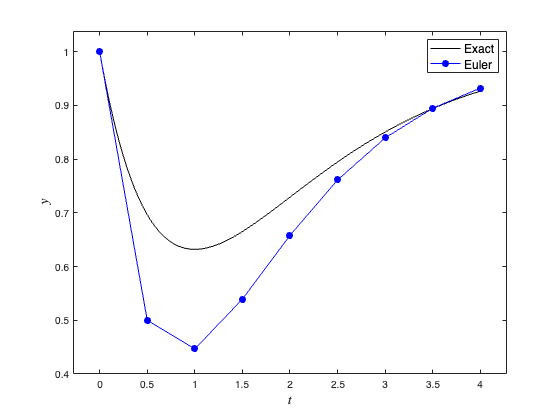

% Calculate exact solution (for plotting)
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=1)
hold on
plot(t, y, 'b-o', LineWidth=1, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'Euler', fontsize=12)

#### Exercise 1.3

Repeat exercise 2 using values of $h = 0.4, 0.2, 0.1, 0.05$ to solve the IVP. 

(a) Produce a plot of the numerical solutions on the same axes. 

(b) Calculate the global truncation error for $y(1)$ and present your results as a table and a plot of the global truncation error against the step length $h$. 

(c) Comment on your results. What do they tell you about the Euler method?

Hint: you can use the NumPy command `idx = np.argmin(abs(t - t0))` or the MATLAB command [`~,idx] = min(abs(t - t0))` to determine the index of the value in the array `t` which is closest to `t0`.

**Solution**

(a)

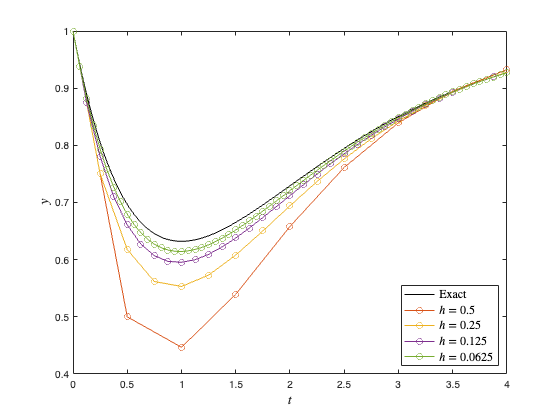

% Plot the exact solution
plot(texact, yexact, 'k', LineWidth=1)
hold on
 
% Loop through h values and calculate the solutions
hvals = [0.5, 0.25, 0.125, 0.0625];
for h = hvals
    [t, y] = solveIVP(f, tspan, y0, h, @euler);
    plot(t, y, 'o-')
end
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', '$h=0.5$', '$h=0.25$', '$h=0.125$', '$h=0.0625$', ...
    Location='southeast', FontSize=12, Interpreter='latex')
hold off

(b)

% Loop through h values and calculate errors
for i = 1 : 1
    errors = [];
    fprintf("Exact solution: y(1) = %1.6f\n", exact(1))
    fprintf("|   h   |  Euler   |  Error   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for h = hvals
        [t, y] = solveIVP(f, tspan, y0, h, @euler);
        [~, idx] = min(abs(t - 1));
        errors = [errors, abs(y(idx,1) - exact(1))];
        fprintf("| %1.2f | %9.6f | %1.2e |\n", h, y(idx), errors(end))
    end
end

Exact solution: y(1) = 0.632121



|   h   |  Euler   |  Error   |

|:-----:|:--------:|:--------:|

| 0.50 |  0.446735 | 1.85e-01 |
| 0.25 |  0.553196 | 7.89e-02 |
| 0.12 |  0.595324 | 3.68e-02 |
| 0.06 |  0.614319 | 1.78e-02 |


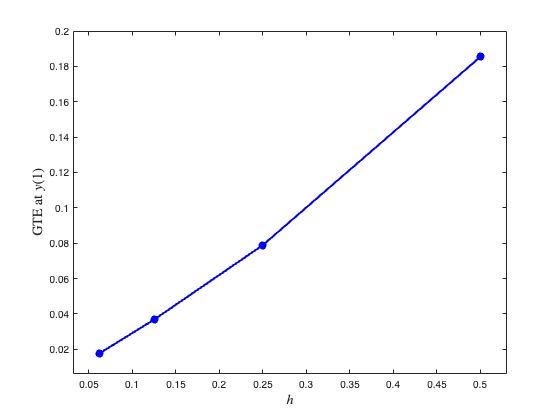


% Plot errors
plot(hvals, errors, 'b-o', LineWidth=2, MarkerFaceColor='b')
axis padded
xlabel('$h$', FontSize=14, Interpreter='latex')
ylabel('GTE at $y(1)$', FontSize=14, Interpreter='latex')

(c) The plot of the global truncation error for $y(1)$ shows that the errors tend to zero as $h$ decreases in a roughly linear fashion indicating that the Euler method is first-order accurate.

#### Exercise 1.4

`The `motion of a pendulum can be modelled by the following ODE


$$\theta'' + \frac{g}{L} \sin(\theta) = 0,$$


where $\theta$ is the angle between the pendulum and the vertical, $L$ is the length of the pendulum and $g=9.81\text{ms}^{-2}$ is the acceleration due to gravity.

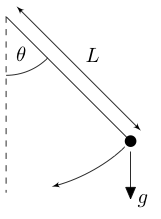

Write a program that solves this IVP using the Euler method with $h=0.001$ over the interval $t\in [0, 5]$ for a pendulum of length $L = 1$ set at an initial angle $\theta = \frac{\pi}{2}$. Produce a plot of the displacement angle $\theta$ against $t$.

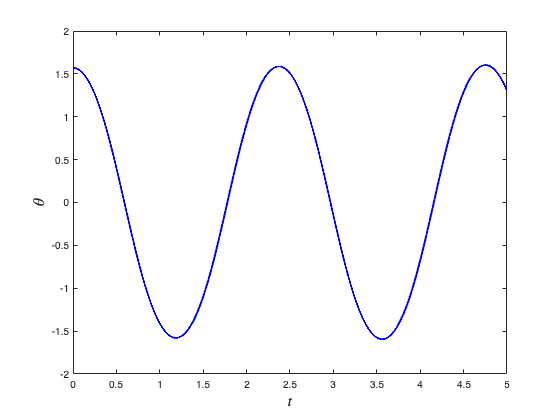

% Define ODE
f = @(t, y) [y(2), -9.81 * sin(y(1))];

% Define IVP
tspan = [0, 5];
y0 = [pi / 2, 0];
h = 0.001;
g = 9.81;
L = 1;

% Solve IVP
[t, y] = solveIVP(f, tspan, y0, h, @euler);

% Plot solution
plot(t, y(:, 1), "b-", LineWidth=2, MarkerFaceColor="b")
xlabel("$t$", FontSize=16, Interpreter="latex")
ylabel("$\theta$", FontSize=16, Interpreter="latex")

## Functions

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver)

% Define t and y arrays
t = (tspan(1) : h : tspan(2));
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : length(t) - 1
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Euler method

function y = euler(f, t, y, h)

y = y + h * f(t, y);

end